# Simplified model of house temperature behaviour

This livescript is a brief manual in support of the app ***housetemperature_story.mlapp***.   This is a simple interface to understand the behaviour of simple thermal systems comprising some heat capacity, heat loss, heat supply and an external environment including wind chill and changing temperature. 

The system has simple first order dynamics and users can observe the impact of simple parameter changes on this behaviour. The later tabs allow users to explore the concept of fedback control for maintaining the desired temperature. First they are encouraged to try manual control and then a systematic PI compensation. The final tab allows evaluation of on-off control and PI in a scenario with a realistic and randomly changing external environment.  

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context and app organisation

- TAB 1: Investigating the impact of parameter changes on open-loop behaviour

- TAB 2: Standard open-loop modelling

- TAB 3: Manual control

- TAB 4: PI control

- TAB 5: Control with uncertainty

- Supporting MATLAB code for analysis

## 1. Engineering context and app organisation

### 1.1 The app organisation

The app is organised into multiple tabs which gradually take the user through an entire control design process, beginning at modelling and finishing at control evaluation. Logically a user would begin a the first tab and work through these systematically. Figures in the following sections will show more detail.

- The top left contains sliders with which the user can set the main system values for the simulations. These sliders are used for all the tabs. 

- The top right has figures which are used for all the tabs.

- The tab window is in the bottom left and has the following options. When selecting a tab, the tab specific options will appear in that part of the window.

- Open-loop behaviour

- Open-loop modelling

- Manual control

- PI control

- Control with uncertainty

In general terms, the top right figure shows the most important response information and, includes memory of previous simulations where appropriate (tabs 1,2,4).

The top middle figure shows the illustration of the house, its temperature (by colour) and heating (size of the red box).

The bottom right figure displays the heating signal and the values assumed for the environment parameters (e.g. wind and external temperature).

The responses can be animated or not using the button in the top left. Animation allows the user to relate the behaviour to the real system, but it does mean waiting about 10 seconds between each simulation. Animation is essential in tabs 3 and 5 and cannot be turned off.

#### Remarks:

- The user can skip to any tab randomly should that be desirable; there should be no interdependencies apart from the very last tab which pulls the PI parameters from tab 4.

- Users may find it helpful to refresh the figures (button at top left) when moving to a new tab. This is not done automatically so that users do not unexpectedly lose some plots they may wish to save or go back to.

- In some tabs, you can disable the animation to see quicker responses using the 'animation on/off' button at the top left.

### 1.2 Modelling background

We consider that house temperature ***T ****(deg)* can be represented as a simple thermal system model. Take the system to have thermal capacitcance ***C*** (J/deg), heat loss to the environment (***k*** W/deg), heat supply ***W*** (watts) and external temperature $T_e$ (deg). A simple model is then given from the differential equation:


$$C\frac{\mathrm{dT}}{\mathrm{dt}}+k\left(T-T_e \right)=W$$


As the basic model is a 1st order differential equation, it is common place to model these in time constant form.


$$\frac{C}{k}\frac{\textrm{dT}}{\textrm{dt}}+T=\frac{1}{k}\left(W+kT_e \right)\;\;\;\Leftrightarrow \;\;\;\;\tau \frac{\textrm{dv}}{\textrm{dt}}+v=T_{\textrm{ss}}$$


where the time constant $\tau =\frac{C}{k}$  gives an indicator of the convergence rate (typically about 3 time constants to be within 5% of steady-state) and $T_{\textrm{ss}} =\frac{1}{k}\left(W+kT_e \right)$ is the expected steady-state (with no disturbances). A simple example is plotted here. For convenience, the time scale is expressed in hours and the gain is expressed in deg/kW.

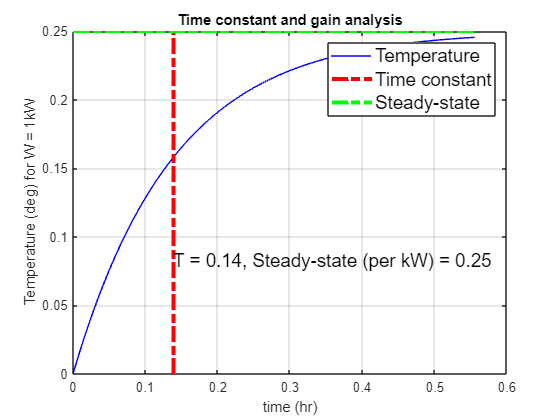

C=2*10^6;
k=4*10^3;
W = 10^3;
Te=0;
tau=C/k;
Tss=(W+k*Te)/k;
time = linspace(0,4*tau,201);
T = (1-exp(-time/tau))*W/k;
tau=tau/3600;


figure; clf
plot(time/3600,T,'b');
hold('on') ;
plot([tau,tau],[0,Tss],'r-.','linewidth',3)
plot([0,4*tau],[Tss,Tss],'g-.','linewidth',3);
kkk=legend('Temperature','Time constant','Steady-state');
set(kkk,'fontsize',14);
text(tau,Tss/3,['T = ',num2str(round(tau,2)),', Steady-state (per kW) = ',num2str(Tss)],'fontsize', 14);
title('Time constant and gain analysis')
xlabel('time (hr)');
ylabel('Temperature (deg) for W = 1kW')
grid('on');
hold('off');

In practice, the external factors and the input change and thus we need to be slightly more careful with our modelling assumptions.


$$C\frac{\mathrm{dT}}{\mathrm{dt}}+k\left(T-T_e \right)=W\longrightarrow \;T\left(s\right)=G\left(s\right)W\left(s\right)+H\left(s\right)T_e \left(s\right)$$


Moreover, changes in wind speed can cause changes in wind chill and thus change the effective value of the parameter ***k*** as heat may be drawn off more quickly in a strong wind. Hence, in this app, the parameter ***k*** is assumed to be linearly dependent on wind speed, that is, it increases with wind speed. Consequently the models ***G(s), H(s)*** are not fixed during the simulation, if the wind is changing.

For simplicity, as this file is for illustrative purposes, the simulation discretises the model at a relatively fast sample rate and ignores the associated discretisation errors (which would be swamped by other more realistic parameter approximation errors in reality anyway).

## 2. TAB 1: Investigating the impact of parameter changes on open-loop behaviour

We are particular interested in how parameter changes effect the temperature behaviour and may wish to ask questions such as the following.

- What happens if the house gets bigger (that is C is bigger)? How does this effect time constant/convergence rate and the steady-state?

- How does wall insulation (parameter k) affect the behaviour?

- How does the heat supply W affect behaviour?

- How do the external temperature and wind affect behaviour?

A general solution (for a fixed environment) is known to take the form:

$T\left(t\right)=\left\lbrack T\left(0\right)-T_{\mathrm{ss}} \right\rbrack e^{-\frac{t}{\tau }} +T_{\mathrm{ss}}$ ;  $T_{\textrm{ss}} =\frac{1}{k}\left(W+kT_e \right)$;  $\tau =\frac{C}{k}$

so one can analyse this equation to determine the expected behaviours.

The user is encouraged to do some thought experiments on the above, and then use the app to validate their expectations. For example:

- Changing C changes the size of the house:

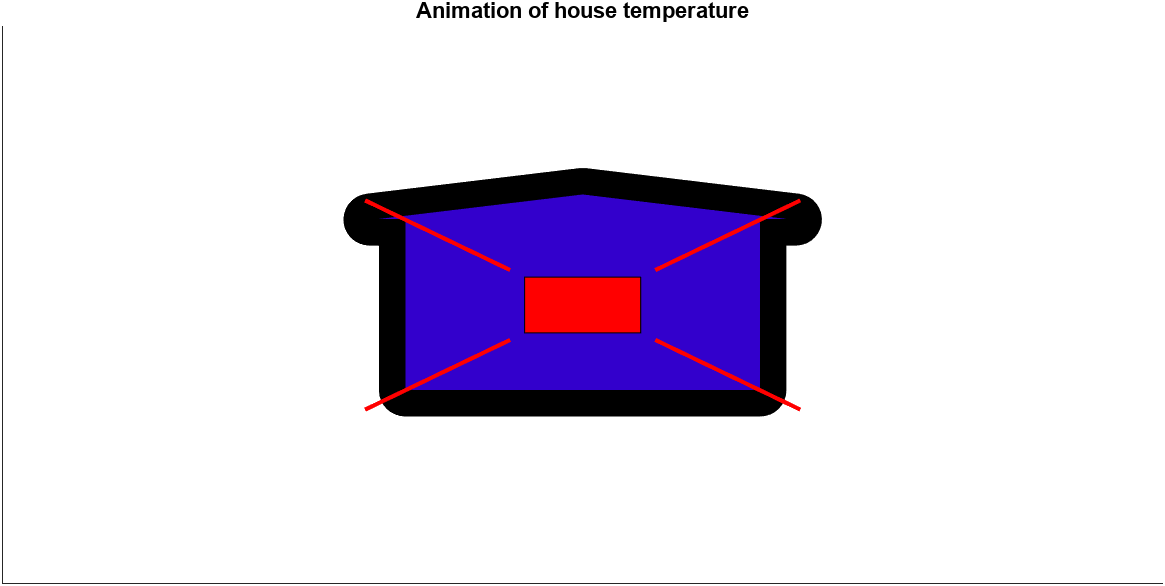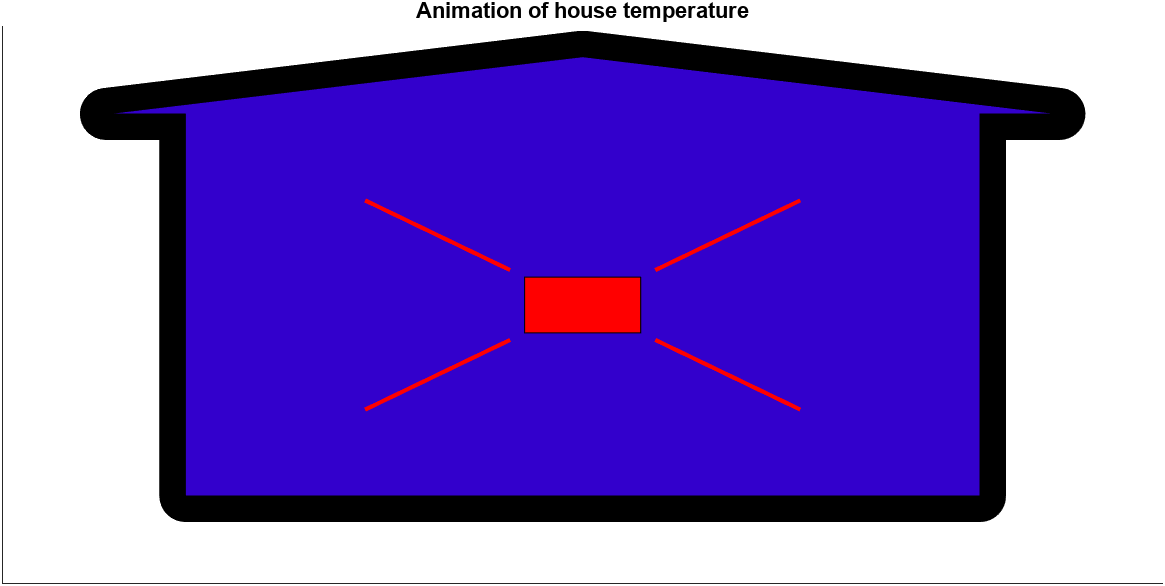

- Changing k changes the wall thickness (to represent heat loss) and changing W changes the red rectangle size ( to represent a larger or smaller fire).

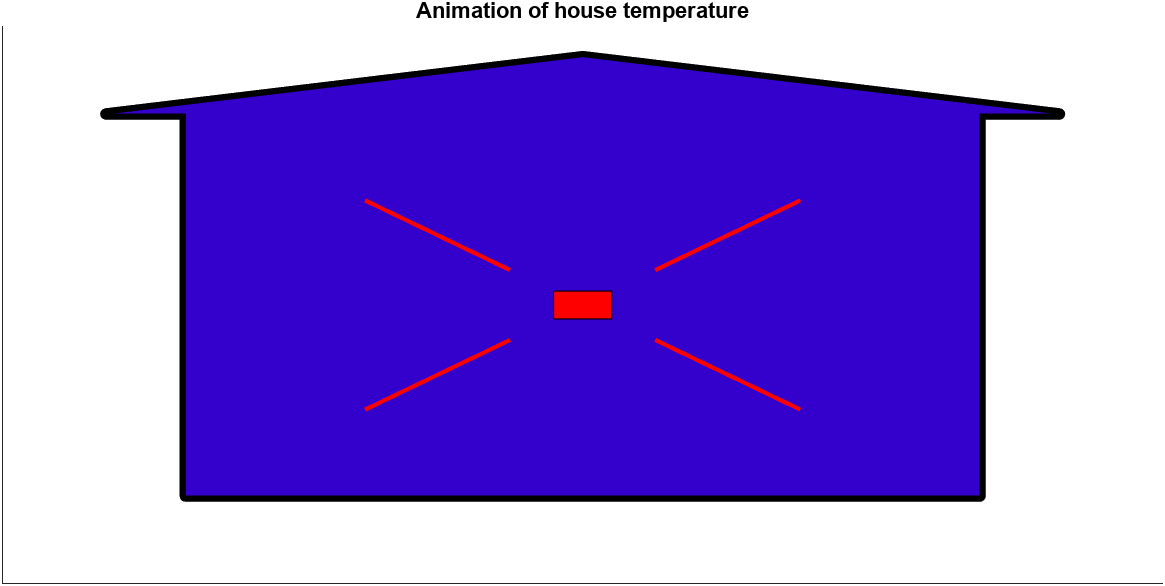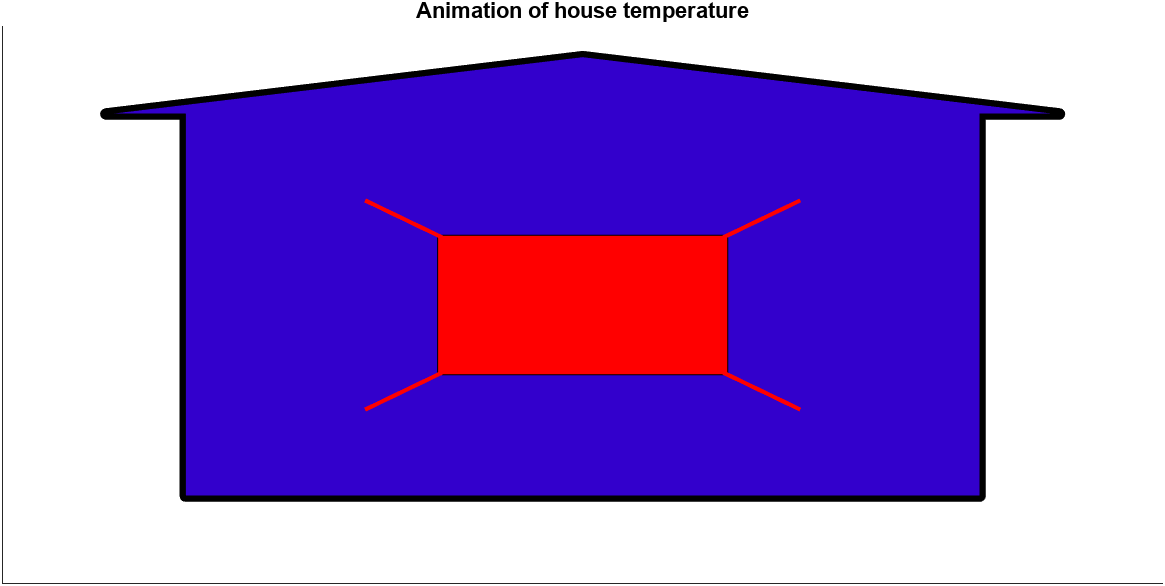

- Changing the temperature changes the colour (bright blue for cold, purple for warm and red for hot).

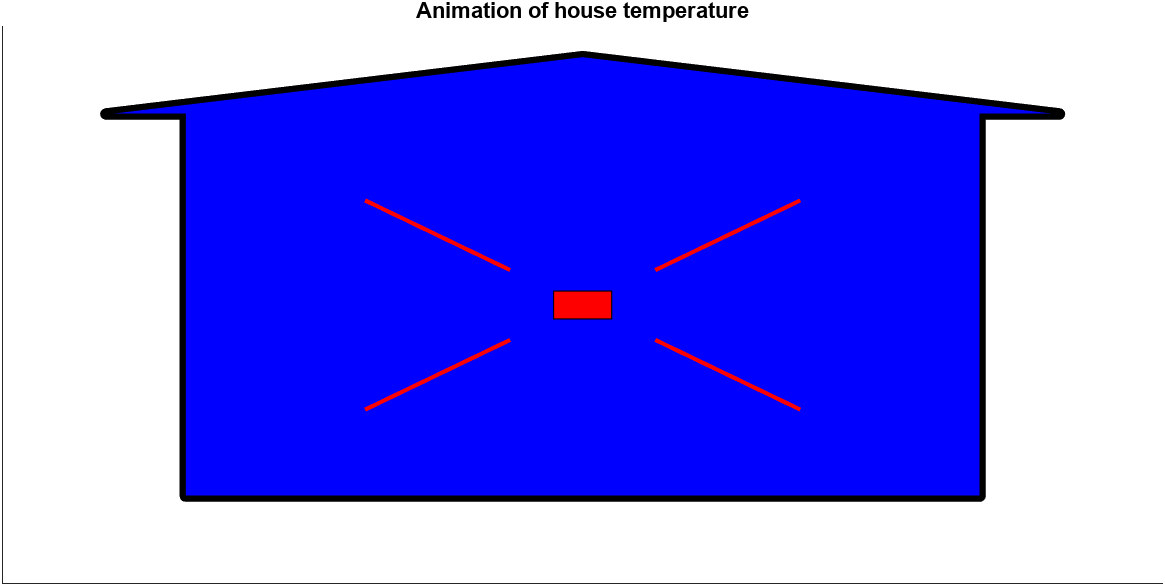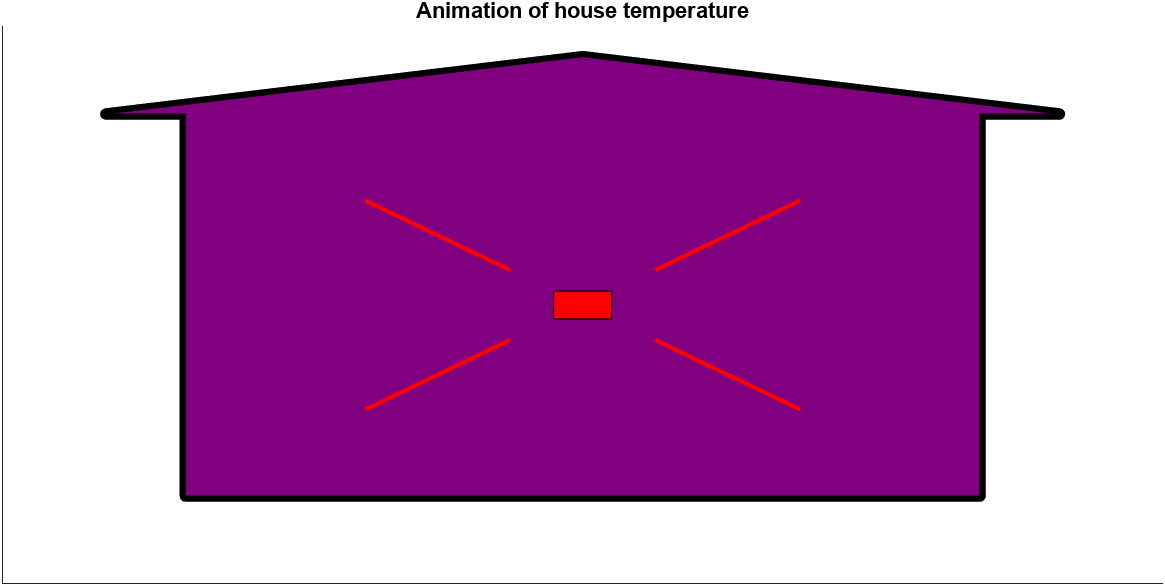

- Simulations with different parameter choices can be saved to allow systematic investigations. 

- The drop down boxes can be used to select how environmental factors are included and the sliders can be used to select the desired values for other parameters.

- Figures will store previous tests until refresh is selected, so users can undertake systematic thought experiments and test for trends.

**CHALLENGE**: Set a value for the heating to achieve the desired temperature (20 degrees). What happens when you change the external temperature, or wind, or make minor changes to  thermal capacity (e.g. people come and go) or heat loss (e.g. open windows).

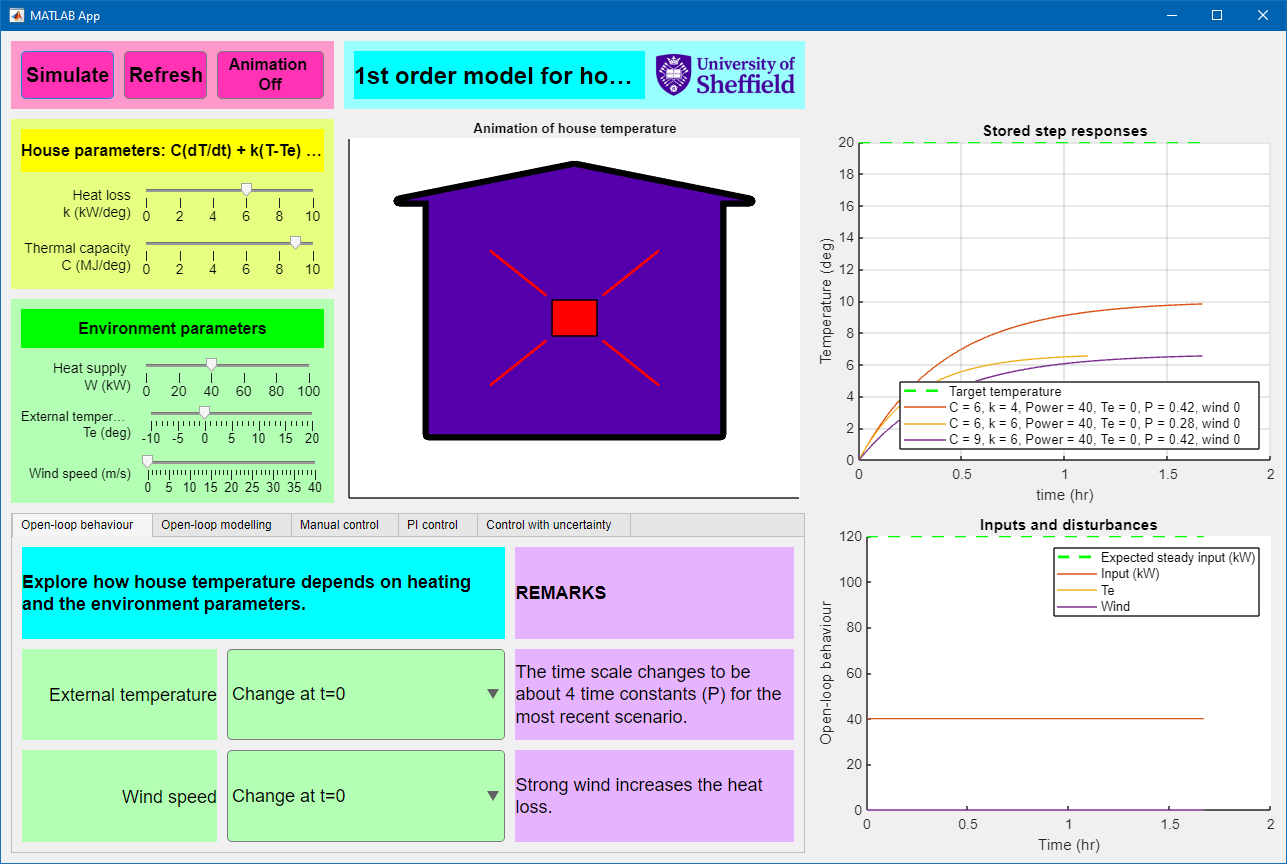

## 3. TAB 2: Standard open-loop modelling

As mentioned in the previous subsection, it is normal to represent 1st order models in a time constant form as this gives insight into the behaviours.

$\tau \frac{\mathrm{dT}}{\mathrm{dt}}+T=\mathrm{KW}$.  The time constant $\tau$ gives a clear indicator of convergence time (typically 3-4$\tau$) and the gain $K$ tells us the expected steady-state $\mathrm{KW}$. In practice the information might be used to determine the parameters from a step response, as show in section 1 above.

A standard first order analysis is covered in numerous other files such as***: firstordermodels_response_characterisation.mlapp*** and [`firstordermodels_responses_analysis_and_feedback.m`](matlab: firstordermodels_responses_analysis_and_feedback)

The 2nd tab is shown in the figure below. The core change from tab 1 is the 'new' figure in the bottom left which illustrates the time constant and gain modelling for the current scenario. Also, for simplicity so the focus can be on modellng, wind speed and external temperature are treated as zero in this tab.

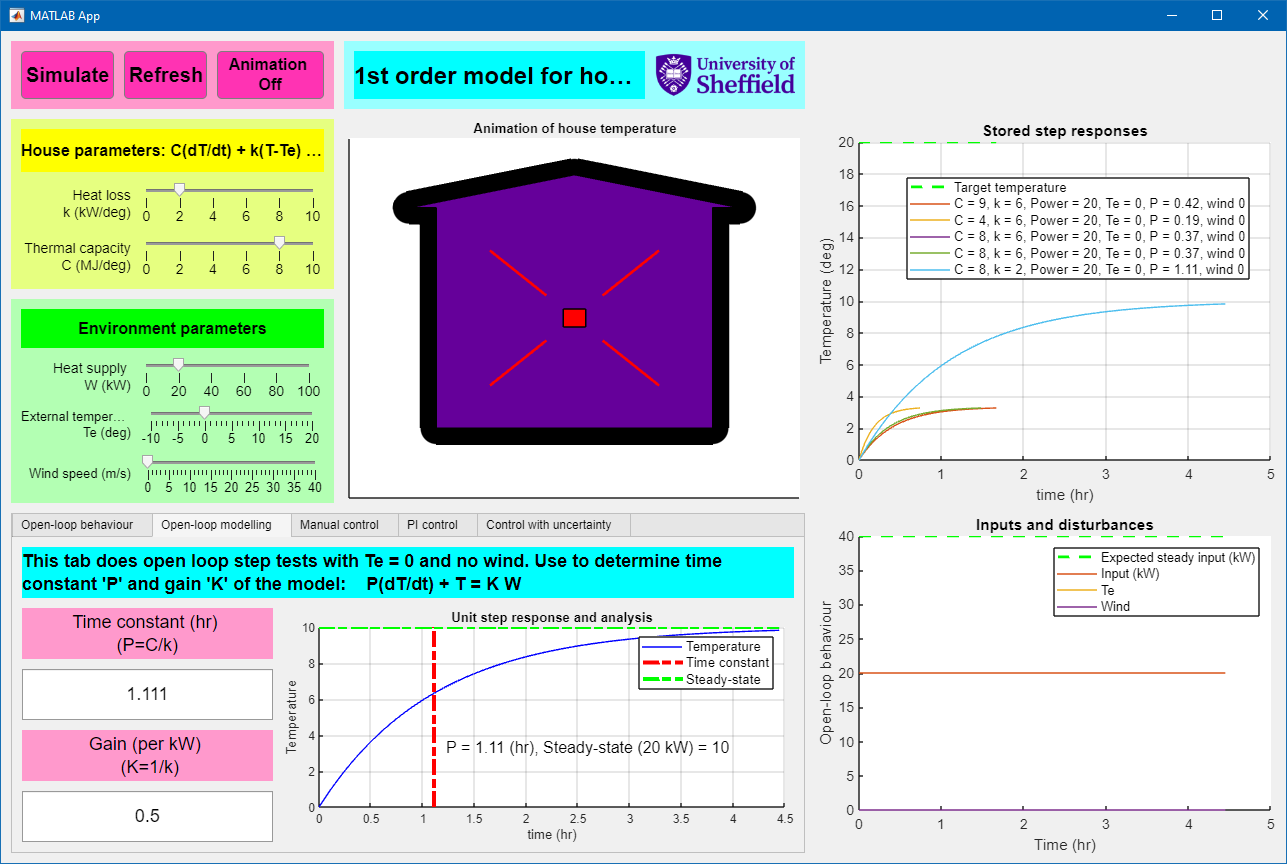

## 4. TAB 3: Manual control

It will have been clear from tab 1, then in general one cannot simply set a value for the heating to achieve the desired temperature (20 degrees). What happens when you change the external temperature, or wind, or make minor changes to  thermal capacity (e.g. people come and go) or heat loss (e.g. open windows). The temperature varies due to a number of factors, some known and some not and thus, simply guessing the required heating power is unlikely to be effective in general.

Of course, humans commonly interfere, that is, we keep changing the heating power to make a room/building more comfortable. The manual control button allows you to experiment with that process and evaluate, how effective is this in practice?

If you make the external environment constant, that is, no wind and Te=0, then you will probably manage fine. However, what happens when these external factors keep changing? You will quickly see than manual control is tedious and not as effective as you might like. The buttons in the tab allow you to include/exclude disturbances but note, these are still bounded by the values in the sliders in the green box above.

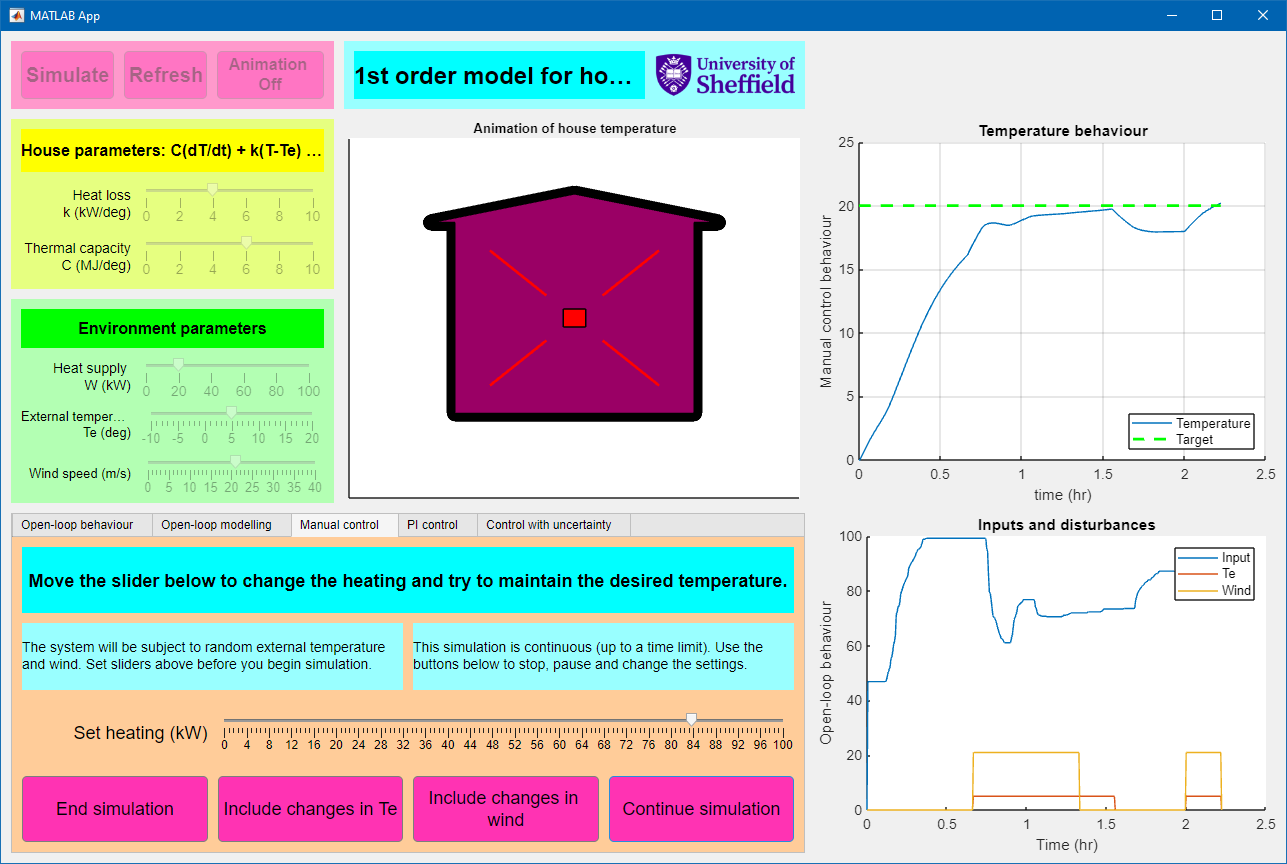

## Tab 4: PI control

The fourth tab uses automatic control, in this case proportional and integral control. The transfer function $C\left(s\right)=\left(K_p +\frac{K_i }{s}\right)$is the PI compensator and *G(s)* represents the system model.

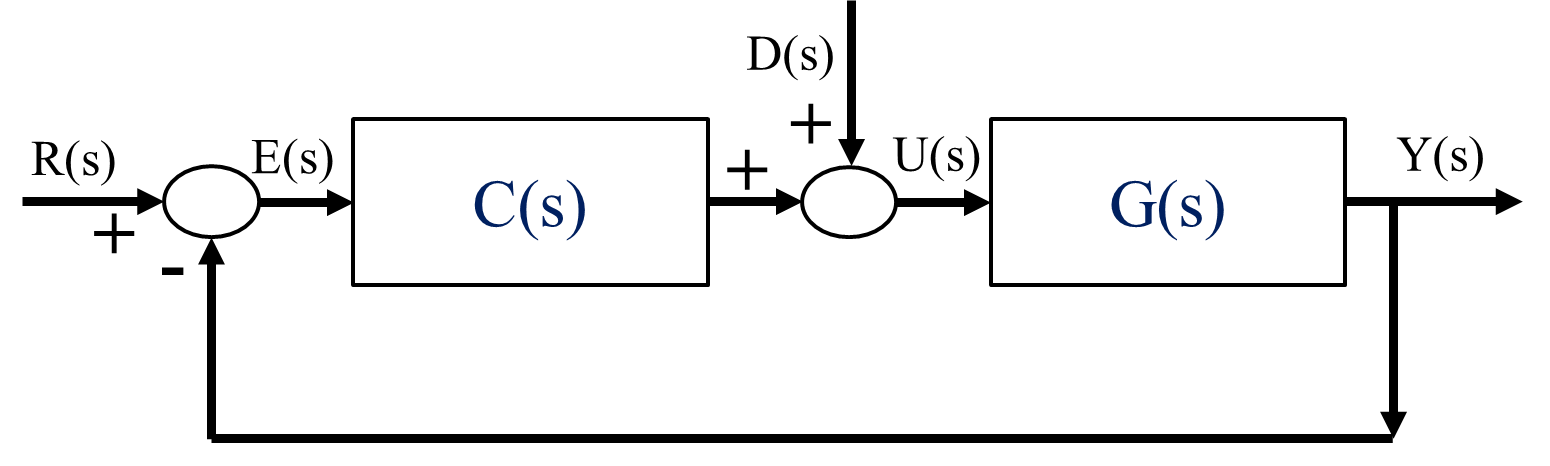

The sliders in the tab allow the user to select values for the proportional and integral parameters and, as elsewhere, the values in the upper sliders can also still be deployed. Consequently, users can undertake systematic studies of how changing individual parameters affects the closed-loop control, as illustrated below. 

There are standard rules for the selection of the parameters $K_p ,K_i \;$but a simple rule base is as follows:


$$K_p =\frac{1}{k};\;K_i =\frac{1}{k\tau }$$


Users can experiment with this choice, and others using the app.

For this tab, the uncertainty in the external temperature and wind are taken as constant throughout the simulation as the intended focus is on the PI design and thus we do not want other factors to distract from this.

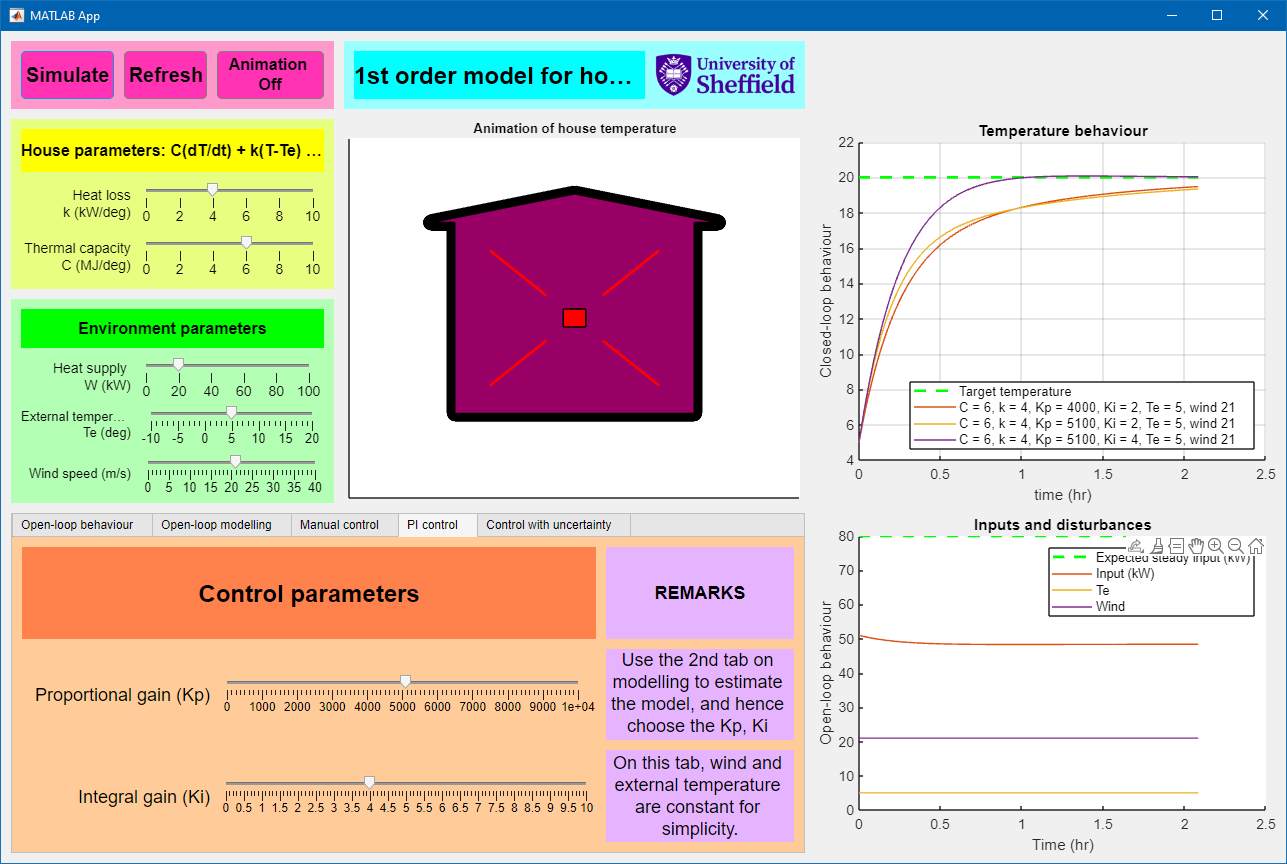

## 6. TAB 5: Control with uncertainty

Having proposed a PI compensator, this tab allows the user to assess its effectiveness in a more realistic scenario where uncertainty is endemic. Each of the sources of uncertainty can be switched on or off with the buttons in the tab.

- Desired temperature is a square wave (dashed green line).

- Wind changes randomly

- External temperature changes randomly

- Temperature measurement is subject to noise (random variance)

- Temperature measurement is subject to delays (which change); this is visible from the difference in the blue and red lines in the top right.

The uncertainty values are changed every 1.6 hours so that the user can assess how well the PI compensation is able to bring the system back to the target temperature.

Secondly, this tab also allows the user to assess the historical and simpler control strategy of on-off control: (i) maximum (limited to 100kW) heating switched on if 2 degrees too cold and (ii) heating off if 2 degrees too warm.

The figure below shows PI for the first 5hr and then a switch to on-off control.

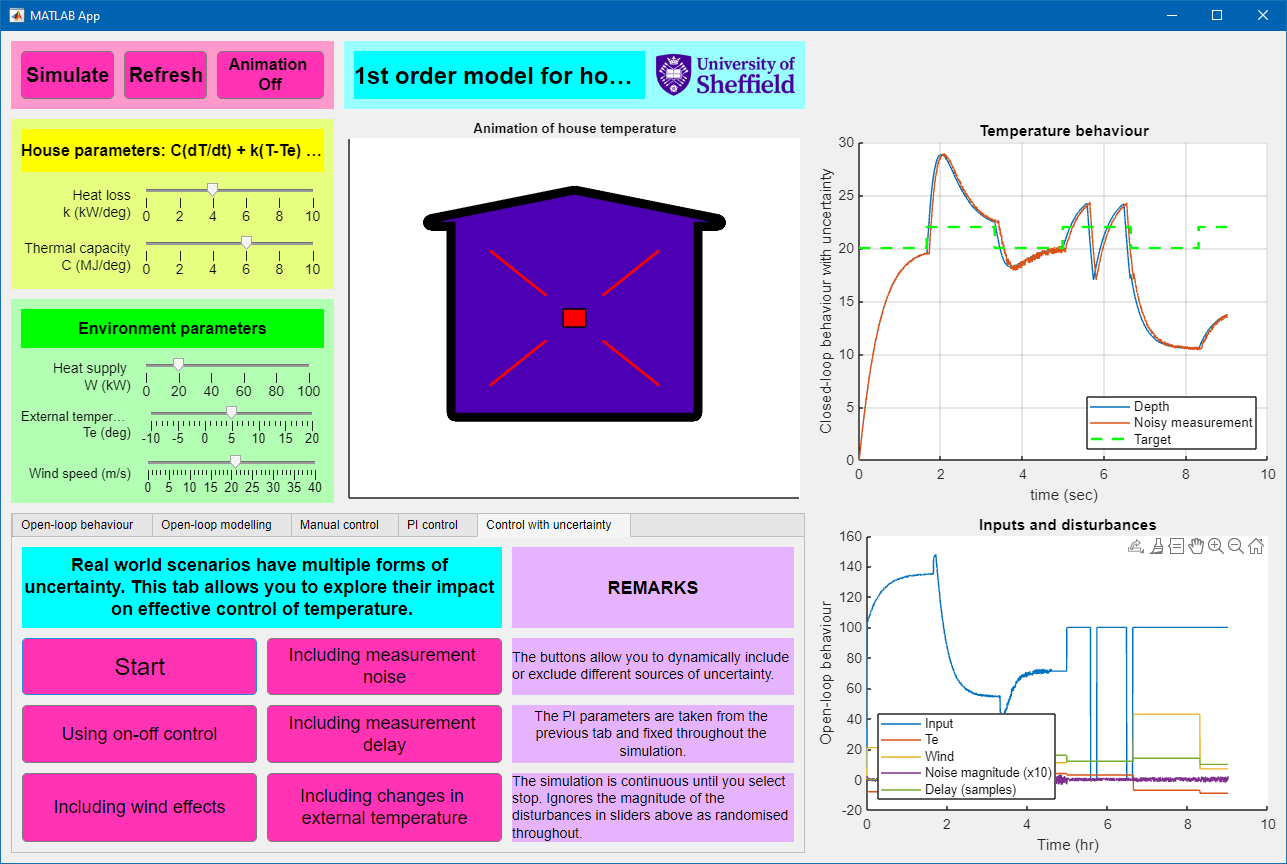

## 7. Supporting MATLAB code for analysis

For simplicity one can use Laplace transforms and ***step.m*** to form the generic open-loop model and the corresponding step responses.

For more information on coding, analysis and design of feedback loops, the user is directed to the appropriate files in the tool box such:

[`closedloop_transferfunctions_with_feedback.m`](matlab: closedloop_transferfunctions_with_feedback)

[`closed_loop_compare_multiple_compensators.m`](matlab: closed_loop_compare_multiple_compensators)

[`closedloop_offset_and_poles.m`](matlab: closedloop_offset_and_poles)

In order  to include the uncertainty correctly, remember to use the open-loop model:


$$C\frac{\mathrm{dT}}{\mathrm{dt}}+k\left(T-T_e \right)=W\longrightarrow \;T\left(s\right)=G\left(s\right)W\left(s\right)+H\left(s\right)T_e \left(s\right)$$


Also, remember that the parameter ***k*** in this model changes with the wind.